Today we are going to download wave data from a sensor located just offshore in Duck, NC. It is a wave buoy (CORMP 44056) at 15m of water depth.

We will be grabbing this data for winter visualization from 11-1-2018 to 3-31-2019 for "winter waves", and 4-1-2019 to 10-31-2019 for "summer waves". We will then visualize the wave conditions from two points of view: wave height/direction and wave period/direction.

We will then select a few of these represenative wave conditions and create wave spectra out of them to visualize the frequency and direction  profiles of the selected wave conditions. the first step is to set up your dependencies to be able to read the buoy data, this is done by running 'setup_nctoolbox' which will add the functions necessary for downloading data to your MATLAB path.

setup_nctoolbox(); %skip this

NCTOOLBOX added to Matlab path


now we will download data using ndbc_get the function takes input arguments:

%ndbc_get(buoy#, [datenum(year,month,day) datenum(year,month,day)]; %skip this

Save the return result to a variable. in this example we use the 15M water depth buoy at the US Army Corps of Engineers Field Research Facility in Duck, NC.

Winter_15m = ndbc_get(44056,[datenum(2018,12,1) datenum(2019,2,31)]);

 Reading location and comment.
 Reading depth.
	Getting data from 2018...
		stdmet
	Getting data from 2019...
		stdmet


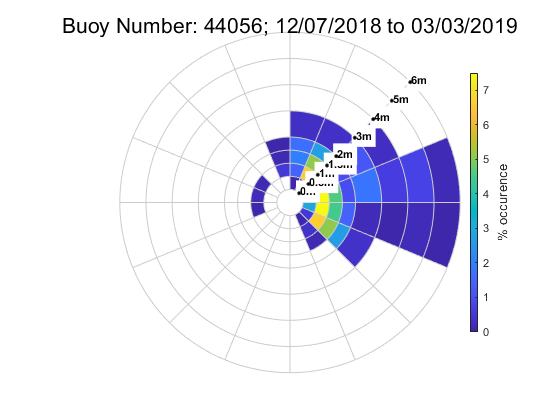

save("Winter_15m")
binBuoyDataHs(Winter_15m)

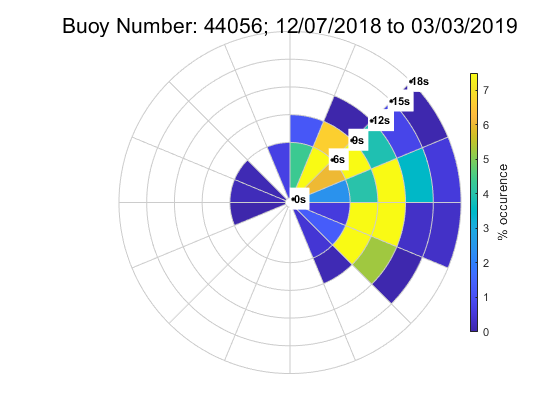

binBuoyDataTp(Winter_15m)

Summer_15m = ndbc_get(44056,[datenum(2019,6,1) datenum(2019,8,31)]);

 Reading location and comment.
 Reading depth.
	Getting data from 2019...
		stdmet


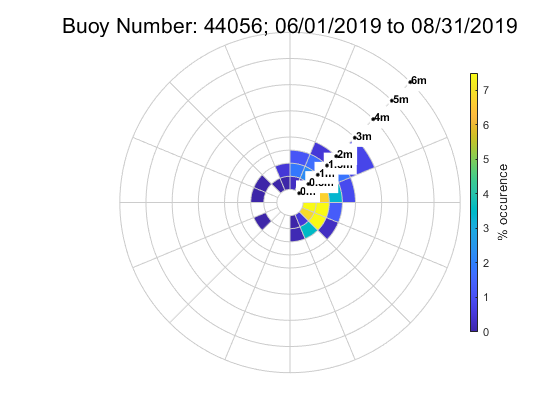

save("Summer_15m")
binBuoyDataHs(Summer_15m)

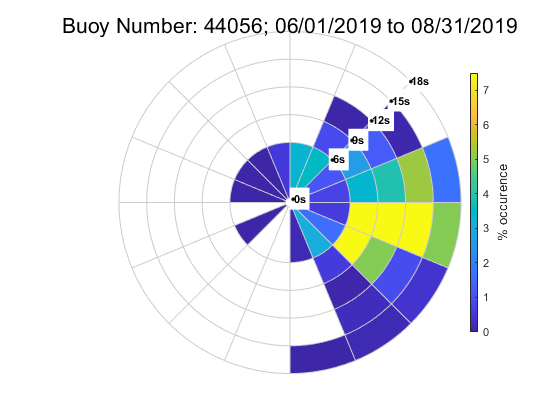

binBuoyDataTp(Summer_15m)

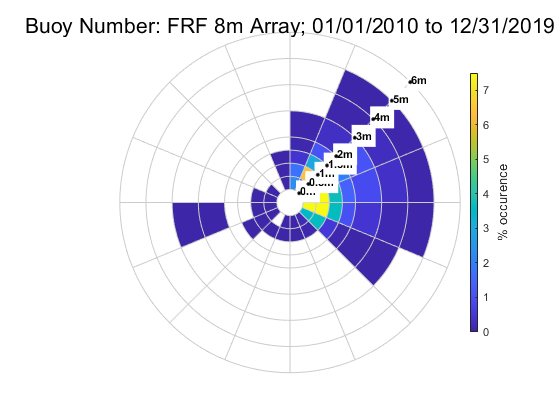

OUT_8m = getwaveFRF(datenum(2010,1,1), datenum(2020,1,1), 10);%skip this
bin8mBuoyData(OUT_8m)%skip this

%load_FRFwave(OUT_8m);

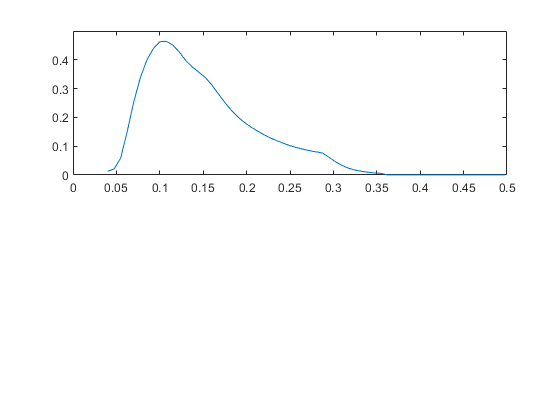

%plot average of all 1D wave spectra gathered from 8m array
OUT_8m.spec1Dmean = mean(OUT_8m.spec1D,1);
subplot(2,1,1)
h = plot(OUT_8m.frqbin, OUT_8m.spec1Dmean);

title('Mean 1D wave Spectra');

Index exceeds the number of array elements (44).

'title' appears to be both a function and a variable. If this is unintentional, use 'clear title' to remove the variable 'title' from the workspace.

xlabel('Frequency (Hz)');
ylabel('Wave Energy');
%use the 1D wave spectra to calculate frequency spreading

%plot average of all directional spectra 
subplot(2,1,2)
h = histogram(OUT_8m.Dp);
title('Peak Direction Histogram');
xlabel('Direction in Degree');
ylabel('Count');
%use the directional histogram to calculate directional spreading

%fmin = minimum spectral freuency
%fmax = maximum spectral frequency
%df = freguency resolution
%FM1 = peak frequency
%gam1 = frequency spreading
%Hs1 = significant wave height
%nn1 = directional spreading
%theta1 = peak direction

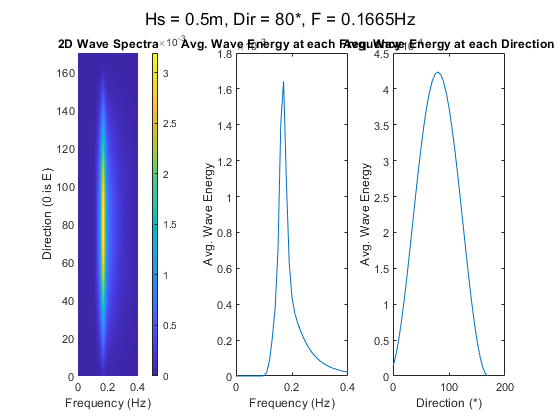

fmin = .0;
fmax = .4;
df = .01;
FM1 = .1465;
gam1 = 3.3;
nn1 = 2;
Hs1 = .4;
theta1 = 72;
[freq, alpha, spec1] = TMA_2peak(fmin,fmax,df,FM1,gam1,Hs1,nn1,theta1,0,0,0,0,0);